% 在程序开始时关闭警告
warning('off', 'MATLAB:structOnObject');
clear; clc; close all;
time_begin = tic;

dim = 2;

ncx = 3; % 奇数，确保有中心单元
ncy = 1;  % y方向1个单元（一维问题）
ncz = 1;  % z方向1个单元

% 计算域范围调整为 [0,1] 以匹配解析解
xmin = 0;
xmax = 1;
ymin = 0;
ymax = 1;
zmin = 0;
zmax = 1;

% 定义要扫描的Peclet数范围
Pe_L_values = -10:1:10; % 从-10到10
center_dimensionless_temps = zeros(size(Pe_L_values)); % 存储中心点无量纲温度

% 对不同Pe数进行扫描
nsteps = 1e3;
res_freq = 1e3;
out_freq = 5e3;
niter_t = 20; relax_t = 0.9; 
res_t = 1e-2;
temp_tol = 1e-4;
con_val = 1.0; % 固定导热系数
dens = 1.0; mu = 1e-3; spheat_val = 0.0; % 比热设为0，稳态问题

%% 计算解析解
figure;
analytical_dimensionless_temps = zeros(size(Pe_L_values));
for i = 1:length(Pe_L_values)
    Pe_L = Pe_L_values(i);
    if Pe_L == 0
        % 纯扩散情况：线性分布，中心点无量纲温度为0.5
        analytical_dimensionless_temps(i) = 0.5;
    else
        % 一维对流扩散解析解：T(x) = (exp(Pe_L*x) - 1) / (exp(Pe_L) - 1)
        % 计算 (φ_C - φ_W)/(φ_E - φ_W)
        x_C = 0.5; % 中心点位置
        x_W = 0.5 - 1/(ncx-1); % 西侧相邻点位置
        x_E = 0.5 + 1/(ncx-1); % 东侧相邻点位置
        
        phi_C = (exp(Pe_L*x_C) - 1) / (exp(Pe_L) - 1);
        phi_W = (exp(Pe_L*x_W) - 1) / (exp(Pe_L) - 1);
        phi_E = (exp(Pe_L*x_E) - 1) / (exp(Pe_L) - 1);
        
        analytical_dimensionless_temps(i) = (phi_C - phi_W) / (phi_E - phi_W);
    end
end
plot(Pe_L_values, analytical_dimensionless_temps, 'r--', 'LineWidth', 2, 'DisplayName', '解析解');
hold on;

% 设置对流格式 - 'centraldifference'或'upwind'
for scheme_num = 1:2
    switch scheme_num
        case 1
            scheme_name = 'centraldifference';
            line_style = 'bo-';
        case 2
            scheme_name = 'upwind';
            line_style = 'gs-';
    end

    for pe_idx = 1:length(Pe_L_values)
        Pe_L = Pe_L_values(pe_idx);
        
        % 根据Pe数计算导热系数和流速
        if Pe_L == 0
            u_val = 0.0; % 纯扩散情况
        else
            u_val = Pe_L * con_val; % u = Pe_L * Γ (因为ρ=1, L=1)
        end

        fprintf('\n=== 正在计算 Pe_L = %.1f (u = %.3f, con = %.3f) ===\n', Pe_L, u_val, con_val);
        
        % 创建网格对象
        mesh = structured_mesh();
        mesh = mesh.create_mesh(dim, ncx, ncy, ncz, xmin, xmax, ymin, ymax, zmin, zmax);
    
        T = 0.5; % 初始条件设为0.5
        mesh = mesh.set_initial_t(T);
        mesh = mesh.create_field_data();
        mesh = mesh.create_coefficient_data(); 
        mesh = mesh.set_scheme(scheme_name);  
        
        % 设置面速度场 - 根据Pe数符号设置流速方向
        mesh = mesh.set_uniform_face_velocity(u_val, 0.0, 0.0);
        mesh = mesh.set_nsteps(nsteps);
        mesh = mesh.set_temperature_solver_param(niter_t, relax_t, res_t, temp_tol);
    
        fluid_properties = fluid_properties(mesh);
        fluid_properties = fluid_properties.set_initial_fluid(dens, mu, con_val, spheat_val);
    
        boundary = boundary(mesh);
        boundary = boundary.create_faces_of_cells(mesh);
        boundary = boundary.create_boundary_fluid(dim, 'wall', 'wall', 'wall', 'wall', 'wall', 'wall');
        
        % 设置温度边界条件
        boundary = boundary.create_boundary_temp(dim, ...
            'xmin', {'constant', 0.0}, ...    % x=0: T=0
            'xmax', {'constant', 1.0}, ...    % x=1: T=1
            'ymin', {'heatflux', 0.0}, ...    % 绝热
            'ymax', {'heatflux', 0.0}, ...    % 绝热
            'zmin', {'heatflux', 0.0}, ...    % 绝热
            'zmax', {'heatflux', 0.0});       % 绝热
    
        % 创建后处理对象
        post = post_processing();
        post = post.Set_res_out_freq(res_freq, out_freq);
    
        % 开始仿真迭代
        for it = 1:nsteps
            % 调用分离求解器
            [mesh.stop_sim, l2_t_over_l2_max_t] = collocated_segregated.solve(it, mesh, fluid_properties, boundary, post);
                
            % 检查收敛条件
            if mesh.stop_sim
                fprintf('在迭代 %d 收敛\n', it);
                break;
            end
            
            if it == nsteps
                fprintf('达到最大迭代次数 %d\n', it);
            end
        end
    
        % 获取中心点及其相邻点的温度，计算无量纲温度
        center_i = ceil(ncx/2); % 中心单元索引
        west_i = center_i - 1;  % 西侧相邻单元索引
        east_i = center_i + 1;  % 东侧相邻单元索引
        
        phi_C = mesh.t(center_i, 1, 1);
        phi_W = mesh.t(west_i, 1, 1);
        phi_E = mesh.t(east_i, 1, 1);
        
        % 计算无量纲温度 (φ_C - φ_W)/(φ_E - φ_W)
        dimensionless_temp = (phi_C - phi_W) / (phi_E - phi_W);
        center_dimensionless_temps(pe_idx) = dimensionless_temp;
        
        fprintf('Pe_L = %.1f, 中心点无量纲温度 = %.6f\n', Pe_L, dimensionless_temp);
        
        % 清理变量，准备下一次计算
        clear mesh fluid_properties boundary post;
    end

    %% 输出结果并绘图
    fprintf('\n=== %s格式结果汇总 ===\n', scheme_name);
    fprintf('Pe_L\t数值解\t解析解\t误差\n');
    for i = 1:length(Pe_L_values)
        error = abs(center_dimensionless_temps(i) - analytical_dimensionless_temps(i));
        fprintf('%6.1f\t%8.6f\t%8.6f\t%8.6f\n', ...
            Pe_L_values(i), center_dimensionless_temps(i), analytical_dimensionless_temps(i), error);
    end

    % 绘制中心点无量纲温度随Pe数变化
    plot(Pe_L_values, center_dimensionless_temps, line_style, 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', sprintf('%s格式数值解', scheme_name));
end


=== 正在计算 Pe_L = -10.0 (u = -10.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-10.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 5.442684e-02, 5.938460e-01, 9.165144e-02, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -10.0, 中心点无量纲温度 = 1.333333



=== 正在计算 Pe_L = -9.0 (u = -9.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-9.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 7.222164e-04, 5.773503e-01, 1.250916e-03, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -9.0, 中心点无量纲温度 = 1.250000



=== 正在计算 Pe_L = -8.0 (u = -8.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-8.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 7.297267e-06, 5.595856e-01, 1.304048e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -8.0, 中心点无量纲温度 = 1.166667



=== 正在计算 Pe_L = -7.0 (u = -7.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-7.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 9.802260e-09, 5.403999e-01, 1.813890e-08, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -7.0, 中心点无量纲温度 = 1.083333



=== 正在计算 Pe_L = -6.0 (u = -6.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-6.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 8.076443e-16, 5.196152e-01, 1.554312e-15, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -6.0, 中心点无量纲温度 = 1.000000



=== 正在计算 Pe_L = -5.0 (u = -5.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-5.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 4.922351e-08, 4.970233e-01, 9.903662e-08, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -5.0, 中心点无量纲温度 = 0.916667



=== 正在计算 Pe_L = -4.0 (u = -4.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-4.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.464518e-06, 4.723775e-01, 3.100313e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -4.0, 中心点无量纲温度 = 0.833333



=== 正在计算 Pe_L = -3.0 (u = -3.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-3.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 7.532502e-06, 4.453845e-01, 1.691236e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -3.0, 中心点无量纲温度 = 0.750000



=== 正在计算 Pe_L = -2.0 (u = -2.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-2.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.727054e-05, 4.156922e-01, 4.154647e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -2.0, 中心点无量纲温度 = 0.666667



=== 正在计算 Pe_L = -1.0 (u = -1.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=-1.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 2.372576e-05, 3.828744e-01, 6.196747e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -1.0, 中心点无量纲温度 = 0.583333



=== 正在计算 Pe_L = 0.0 (u = 0.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=0.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 2.174645e-05, 3.464102e-01, 6.277658e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 0.0, 中心点无量纲温度 = 0.500000



=== 正在计算 Pe_L = 1.0 (u = 1.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=1.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.352909e-05, 3.056560e-01, 4.426248e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 1.0, 中心点无量纲温度 = 0.416667



=== 正在计算 Pe_L = 2.0 (u = 2.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=2.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 5.397044e-06, 2.598076e-01, 2.077323e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 2.0, 中心点无量纲温度 = 0.333333



=== 正在计算 Pe_L = 3.0 (u = 3.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=3.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.171723e-06, 2.078461e-01, 5.637453e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 3.0, 中心点无量纲温度 = 0.250000



=== 正在计算 Pe_L = 4.0 (u = 4.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=4.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 9.205541e-08, 1.484615e-01, 6.200625e-07, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 4.0, 中心点无量纲温度 = 0.166667



=== 正在计算 Pe_L = 5.0 (u = 5.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=5.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 7.197334e-10, 7.994081e-02, 9.003329e-09, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 5.0, 中心点无量纲温度 = 0.083333



=== 正在计算 Pe_L = 6.0 (u = 6.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=6.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.220633e-53, 2.598307e-13, 4.697802e-41, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 6.0, 中心点无量纲温度 = -0.000000



=== 正在计算 Pe_L = 7.0 (u = 7.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=7.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.318217e-10, 9.447550e-02, 1.395300e-09, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 7.0, 中心点无量纲温度 = -0.083333



=== 正在计算 Pe_L = 8.0 (u = 8.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=8.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 3.872019e-07, 2.078461e-01, 1.862926e-06, 
----------------------------
Final iter = 4
it, l2_t/l2_max_t: 4, 0.000000e+00
----------------------------


在迭代 4 收敛


Pe_L = 8.0, 中心点无量纲温度 = -0.166667



=== 正在计算 Pe_L = 9.0 (u = 9.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=9.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 8.666597e-05, 3.464102e-01, 2.501831e-04, 
----------------------------
Final iter = 6
it, l2_t/l2_max_t: 6, 0.000000e+00
----------------------------


在迭代 6 收敛


Pe_L = 9.0, 中心点无量纲温度 = -0.250000



=== 正在计算 Pe_L = 10.0 (u = 10.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: centraldifference


均匀速度场设置: u=10.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.190587e-02, 5.196152e-01, 2.291286e-02, 
----------------------------
Final iter = 11
it, l2_t/l2_max_t: 11, 1.658252e-16
----------------------------


在迭代 11 收敛


Pe_L = 10.0, 中心点无量纲温度 = -0.333333



=== centraldifference格式结果汇总 ===


Pe_L	数值解	解析解	误差


 -10.0	1.333333	0.993307	0.340026
  -9.0	1.250000	0.989013	0.260987
  -8.0	1.166667	0.982014	0.184653
  -7.0	1.083333	0.970688	0.112646
  -6.0	1.000000	0.952574	0.047426
  -5.0	0.916667	0.924142	0.007475
  -4.0	0.833333	0.880797	0.047464
  -3.0	0.750000	0.817574	0.067574
  -2.0	0.666667	0.731059	0.064392
  -1.0	0.583333	0.622459	0.039126
   0.0	0.500000	0.500000	0.000000
   1.0	0.416667	0.377541	0.039126
   2.0	0.333333	0.268941	0.064392
   3.0	0.250000	0.182426	0.067574
   4.0	0.166667	0.119203	0.047464
   5.0	0.083333	0.075858	0.007475
   6.0	-0.000000	0.047426	0.047426
   7.0	-0.083333	0.029312	0.112646
   8.0	-0.166667	0.017986	0.184653
   9.0	-0.250000	0.010987	0.260987
  10.0	-0.333333	0.006693	0.340026



=== 正在计算 Pe_L = -10.0 (u = -10.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-10.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 2.453130e-06, 4.658619e-01, 5.265788e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -10.0, 中心点无量纲温度 = 0.812500



=== 正在计算 Pe_L = -9.0 (u = -9.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-9.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 3.214965e-06, 4.618802e-01, 6.960603e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -9.0, 中心点无量纲温度 = 0.800000



=== 正在计算 Pe_L = -8.0 (u = -8.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-8.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 4.245904e-06, 4.572614e-01, 9.285506e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -8.0, 中心点无量纲温度 = 0.785714



=== 正在计算 Pe_L = -7.0 (u = -7.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-7.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 5.643668e-06, 4.518393e-01, 1.249043e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -7.0, 中心点无量纲温度 = 0.769231



=== 正在计算 Pe_L = -6.0 (u = -6.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-6.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 7.532502e-06, 4.453845e-01, 1.691236e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -6.0, 中心点无量纲温度 = 0.750000



=== 正在计算 Pe_L = -5.0 (u = -5.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-5.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.005283e-05, 4.375707e-01, 2.297419e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -5.0, 中心点无量纲温度 = 0.727273



=== 正在计算 Pe_L = -4.0 (u = -4.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-4.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.331590e-05, 4.279184e-01, 3.111785e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -4.0, 中心点无量纲温度 = 0.700000



=== 正在计算 Pe_L = -3.0 (u = -3.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-3.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.727054e-05, 4.156922e-01, 4.154647e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -3.0, 中心点无量纲温度 = 0.666667



=== 正在计算 Pe_L = -2.0 (u = -2.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-2.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 2.137934e-05, 3.997040e-01, 5.348793e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -2.0, 中心点无量纲温度 = 0.625000



=== 正在计算 Pe_L = -1.0 (u = -1.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=-1.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 2.399143e-05, 3.779020e-01, 6.348586e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = -1.0, 中心点无量纲温度 = 0.571429



=== 正在计算 Pe_L = 0.0 (u = 0.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=0.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 2.174645e-05, 3.464102e-01, 6.277658e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 0.0, 中心点无量纲温度 = 0.500000



=== 正在计算 Pe_L = 1.0 (u = 1.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=1.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.484470e-05, 3.117691e-01, 4.761439e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 1.0, 中心点无量纲温度 = 0.428571



=== 正在计算 Pe_L = 2.0 (u = 2.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=2.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 9.095938e-06, 2.834265e-01, 3.209276e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 2.0, 中心点无量纲温度 = 0.375000



=== 正在计算 Pe_L = 3.0 (u = 3.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=3.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 5.397044e-06, 2.598076e-01, 2.077323e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 3.0, 中心点无量纲温度 = 0.333333



=== 正在计算 Pe_L = 4.0 (u = 4.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=4.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 3.198325e-06, 2.398224e-01, 1.333622e-05, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 4.0, 中心点无量纲温度 = 0.300000



=== 正在计算 Pe_L = 5.0 (u = 5.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=5.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.918566e-06, 2.226922e-01, 8.615323e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 5.0, 中心点无量纲温度 = 0.272727



=== 正在计算 Pe_L = 6.0 (u = 6.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=6.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.171723e-06, 2.078461e-01, 5.637453e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 6.0, 中心点无量纲温度 = 0.250000



=== 正在计算 Pe_L = 7.0 (u = 7.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=7.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 7.301495e-07, 1.948557e-01, 3.747129e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 7.0, 中心点无量纲温度 = 0.230769



=== 正在计算 Pe_L = 8.0 (u = 8.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=8.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 4.644280e-07, 1.833936e-01, 2.532411e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 8.0, 中心点无量纲温度 = 0.214286



=== 正在计算 Pe_L = 9.0 (u = 9.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=9.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 3.014029e-07, 1.732051e-01, 1.740151e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 9.0, 中心点无量纲温度 = 0.200000



=== 正在计算 Pe_L = 10.0 (u = 10.000, con = 1.000) ===


调试：2D网格检测成功，ncz 已设置为 1


对流项离散格式设置为: upwind


均匀速度场设置: u=10.000, v=0.000, w=0.000


it_nl, it, tot_it, norm2, max, rel_norm, : 1, 20, 20, 1.993980e-07, 1.640890e-01, 1.215182e-06, it_nl, it, tot_it, norm2, max, rel_norm, : 1000, 20, 20000, 0.000000e+00, 0.000000e+00, NaN, 

达到最大迭代次数 1000


Pe_L = 10.0, 中心点无量纲温度 = 0.187500



=== upwind格式结果汇总 ===


Pe_L	数值解	解析解	误差


 -10.0	0.812500	0.993307	0.180807
  -9.0	0.800000	0.989013	0.189013
  -8.0	0.785714	0.982014	0.196300
  -7.0	0.769231	0.970688	0.201457
  -6.0	0.750000	0.952574	0.202574
  -5.0	0.727273	0.924142	0.196869
  -4.0	0.700000	0.880797	0.180797
  -3.0	0.666667	0.817574	0.150908
  -2.0	0.625000	0.731059	0.106059
  -1.0	0.571429	0.622459	0.051031
   0.0	0.500000	0.500000	0.000000
   1.0	0.428571	0.377541	0.051031
   2.0	0.375000	0.268941	0.106059
   3.0	0.333333	0.182426	0.150908
   4.0	0.300000	0.119203	0.180797
   5.0	0.272727	0.075858	0.196869
   6.0	0.250000	0.047426	0.202574
   7.0	0.230769	0.029312	0.201457
   8.0	0.214286	0.017986	0.196300
   9.0	0.200000	0.010987	0.189013
  10.0	0.187500	0.006693	0.180807


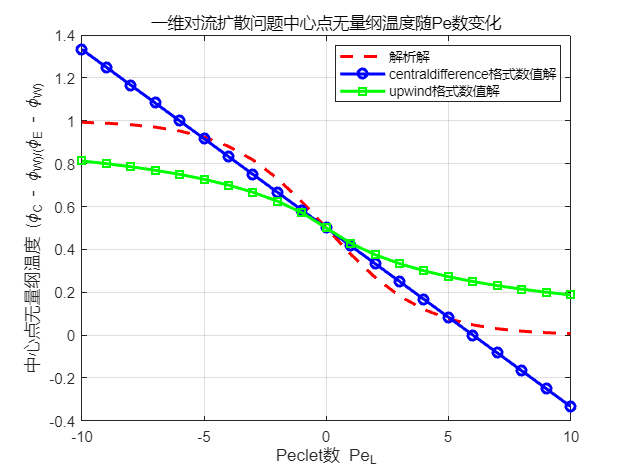


xlabel('Peclet数 Pe_L');
ylabel('中心点无量纲温度 (\phi_C - \phi_W)/(\phi_E - \phi_W)');
title('一维对流扩散问题中心点无量纲温度随Pe数变化');
legend('Location', 'best');
grid on;


%% 计算总运行时间
total_time = toc(time_begin);
fprintf("总运行时间: %.6f 秒\n", total_time);

总运行时间: 53.854240 秒



fprintf('仿真完成！\n');

仿真完成！



% 在程序结束时恢复警告
warning('on', 'MATLAB:structOnObject');